R_SENSE = 0.01;
V_MAX = 6;
I_STALL = 1.2;
I_OP_LIM = 0.3;
F = 1E3;
V_SHUNTMAX = R_SENSE*I_OP_LIM

V_SHUNTMAX = 0.0030

V_OUTMAX = 5;
GAIN = V_OUTMAX/V_SHUNTMAX

GAIN = 1.6667e+03

R1 = 330

R1 = 330

R2 = 560E3

R2 = 560000

C1 = 100E-9

C1 = 1.0000e-07

g = 25/(R2/R1)

g = 0.0147

R3 = 1/(2*pi*F*C1*g)

R3 = 1.0803e+05

T = R3*C1

T = 0.0108


R4 = 34E3

R4 = 34000

Rt = 3.3/(5-3.3)*R4

Rt = 6.6000e+04

R5 = Rt*100E3/(100E3-Rt)

R5 = 1.9412e+05


H = tf([R2/R1],[R3*C1 1])

H =
 
      1697
  ------------
  0.0108 s + 1
 
Continuous-time transfer function.



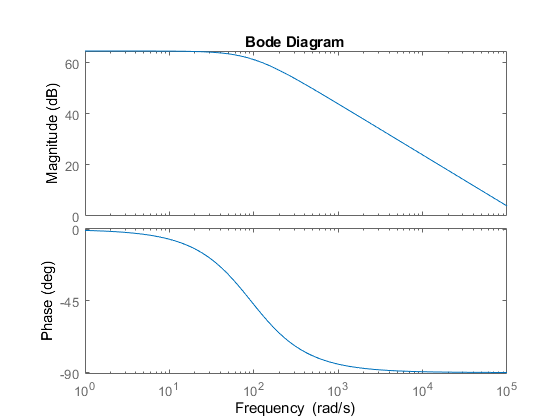

bode(H,{1 100000})